clc
clear
close all

Gqn0=[16,64,256,1024,4096,16384,65536,262144]*1e-6;
vv=[10,20,40,60];

b = 1.5;        % 轮距（m）
L = 4.0;        % 轴距（m）
v = vv(3);      % 车速（m/s）
n0  = 0.1;      % 参考空间频率     （m-1）
n00 = 0.01;     % 路面空间截止频率 （m-1）
Gqn0 = Gqn0(2); % 选择路面等级

tl = L/v;
tb = b/v;

% white noise参数设置
noise_power = 0.01;       % 噪声功率
sample_time = 0.001;      % 采样时间
seed = 23341;             % 随机种子

k11 = 2*pi*n0*sqrt(Gqn0*v);
k12 = -2*pi*n00*v;

k21 = 2/tb+2*pi*n00*v;
k22 = -2/tb;

k31 = 2/tl+2*pi*n00*v;
k32 = -2/tl;

k41 = -(2/tb+2*pi*n00*v);
k42 = 2/tl+2/tb;
k43 = -2/tl;

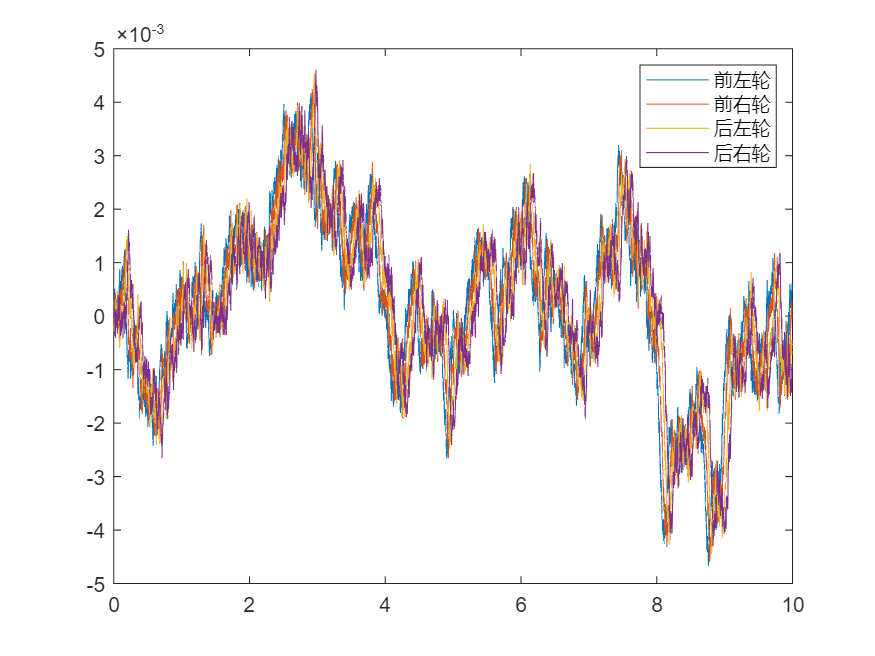

% simulink 求解
options=simset('Srcworkspace','current');
out=sim('P7_son2.slx',[0,10]);

t = out.FL.Time;

q_1 = out.FL.Data;
q_2 = out.FR.Data;
q_3 = out.RL.Data;
q_4 = out.RR.Data;

plot(t,q_1,t,q_2,t,q_3,t,q_4)
legend({'前左轮','前右轮','后左轮','后右轮'})